# MATLAB TD 3

### Nom Complet: Luiz Felipe SPINOLA SILVA

## Exercice 1 : Image et puzzle

Lire l'image de la bibliothèque matlab 'pout.tif'

Afficher côte à côte l'image et son histogramme, donner une interprétation

Comment faire pour étendre l'histogramme et ainsi augmenter le contraste?

Afficher la nouvelle image (I) avec son histogramme côte à côte.

Détecter les contours de I à l'aide de la méthode "canny". Remplacer les contours détectés, par un pixel blanc dans une copie de l'image initiale. Afficher image initiale, détection de contours et image modifiée côte à côte.

Trouver dans l'aide la commande permettant de faire pivoter I de 90 puis de 180°.

Trouver dans l'aide la commande permettant de translater I de 100 pixels vers le bas et de 50 pixels vers la gauche, en comblant avec du noir

Fabriquer un puzzle de quatre pièces avec cette image : créer 4 images représentant chacune un quart de l'image. Les associer dans le désordre pour créer le puzzle désordonné

Sur une même figure, mettre l'image désordre et l'image I.

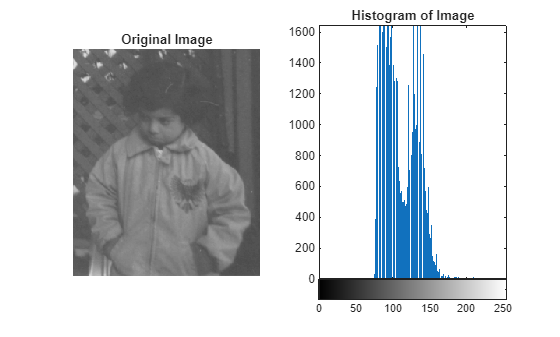

clc; clear; close all;
I = imread('pout.tif');

figure()
subplot(1,2,1)
imshow(I);
title('Original Image');
subplot(1,2,2)
imhist(I);
title('Histogram of Image');

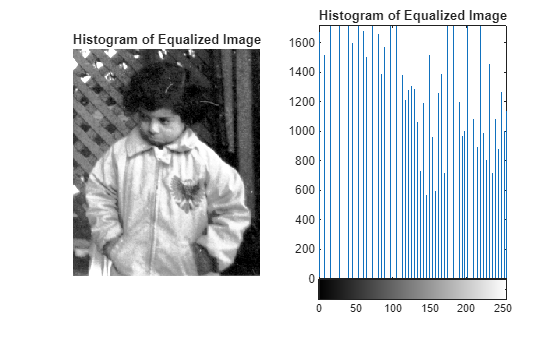

figure()
subplot(1,2,1)
imshow(histeq(I));
title('Histogram of Equalized Image');
subplot(1,2,2)
imhist(histeq(I));
title('Histogram of Equalized Image');

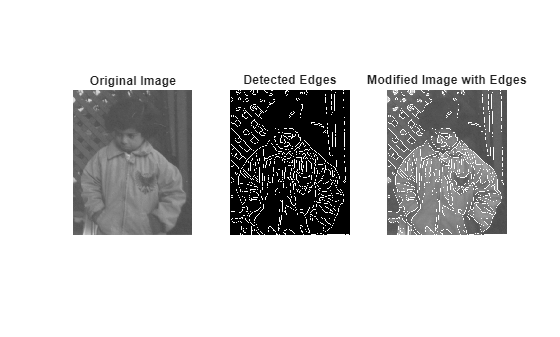

edges = edge(I, 'Canny');
modifiedImage = I;
modifiedImage(edges) = 255;

figure()
subplot(1,3,1)
imshow(I);
title('Original Image');
subplot(1,3,2)
imshow(edges);
title('Detected Edges');
subplot(1,3,3)
imshow(modifiedImage);
title('Modified Image with Edges');

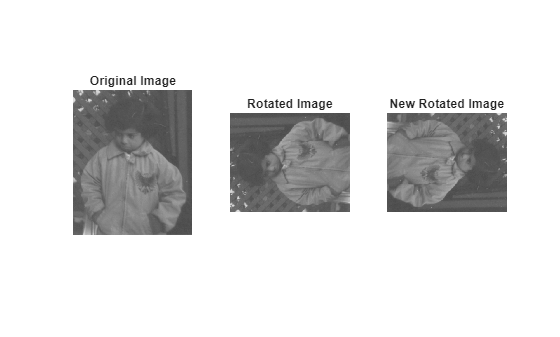

I_rotated = imrotate(I,90);

figure()
subplot(1,3,1)
imshow(I);
title('Original Image');
subplot(1,3,2)
imshow(I_rotated);
title('Rotated Image');
subplot(1,3,3)
imshow(imrotate(I_rotated, 180));
title('New Rotated Image');

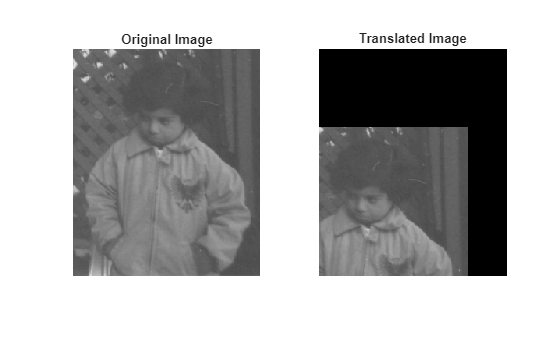

I_translated = imtranslate(I,[-50, 100], 'FillValues',0);

figure()
subplot(1,2,1)
imshow(I);
title('Original Image');
subplot(1,2,2)
imshow(I_translated);
title('Translated Image');

[lignes collones] = size(I);
I_quart_1 = imcrop(I, [1 1 (lignes/2) (collones/2)]);
I_quart_2 = imcrop(I, [1 1 (lignes/2) (collones/2)]);
